%% Valódi LTE Turbo Kód vs. Sima Konvolúciós Kód Szimuláció
% Ez a szkript megmutatja, hogyan kell a valóságban Turbo kódokat
% generálni és dekódolni iteratív algoritmusokkal a mátrixos LDPC
% megközelítés helyett.

clear; clc; close all;

%% 1. Rendszer paraméterek (LTE 3GPP Szabvány alapján)
% Az LTE Turbo kód 8-állapotú (K=4) RSC kódolókat használ.
% Polinomok oktálisan: Visszacsatolás=13, Előrecsatolás=15
K_turbo = 4;
trellis_lte = poly2trellis(K_turbo, [13 15], 13);

dataLen = 1000; % Hasznos adatbitek száma egy keretben

% A Turbo kód "varázsfegyvere": a Keverő (Interleaver) indexek
% Véletlenszerű keverést használunk a bemutató kedvéért.
intrlvrIndices = randperm(dataLen);

% Valódi Turbo Kódoló és Dekódoló objektumok létrehozása (Communications Toolbox)
turboEnc = comm.TurboEncoder('TrellisStructure', trellis_lte, ...
    'InterleaverIndices', intrlvrIndices);

% A Turbo dekódoló ITERATÍV. 4 iteráció általában már szinte tökéletes.
turboDec = comm.TurboDecoder('TrellisStructure', trellis_lte, ...
    'InterleaverIndices', intrlvrIndices, ...
    'NumIterations', 4);

snr_dB_array = 0:0.5:4.0;
max_keret = 1000;
ber_turbo = zeros(size(snr_dB_array));
ber_viterbi = zeros(size(snr_dB_array));

fprintf('--- Szimuláció indítása: Sima RSC vs. Valódi ITERATÍV Turbo Kód ---\n');

--- Szimuláció indítása: Sima RSC vs. Valódi ITERATÍV Turbo Kód ---



for snr_idx = 1:length(snr_dB_array)
    snr = snr_dB_array(snr_idx);
    hiba_turbo = 0;
    hiba_vit = 0;

    nv = 10^(-snr/10); % Zaj variancia (szükséges a pontos LLR-hez)

    for k = 1:max_keret
        %% --- ADATGENERÁLÁS ---
        data = randi([0 1], dataLen, 1);

        %% --- RENDSZER 1: VALÓDI TURBO KÓD ---
        % 1. Kódolás (Kimenet: kb. 3000 bit, R=1/3 kódarány)
        enc_turbo = turboEnc(data);

        % 2. BPSK Moduláció: 0 -> +1, 1 -> -1 (FONTOS IPARI KONVENCIÓ!)
        tx_turbo = 1 - 2 * enc_turbo;

        % 3. AWGN Csatorna
        rx_turbo = awgn(tx_turbo, snr, 'measured');

        % 4. LLR Kiszámítása BPSK esetén (2 * y / variancia)
        % Mivel 0 -> +1 volt, a pozitív RX pozitív LLR-t ad (esély a 0-ra)
        llr_turbo = (2 * rx_turbo) / nv;

        % 5. Iteratív Turbo Dekódolás
        dec_turbo = turboDec(llr_turbo);
        hiba_turbo = hiba_turbo + biterr(data, dec_turbo);

        %% --- RENDSZER 2: SIMA RSC KÓD (Referencia) ---
        % Hogy fair legyen a verseny, ugyanazt a kódolót használjuk,
        % de csak egy darabot, keverő nélkül. (Kimenet: 2000 bit, R=1/2)
        enc_vit = convenc(data, trellis_lte);

        % BPSK Moduláció
        tx_vit = 1 - 2 * enc_vit;

        % Csatorna zaj
        rx_vit = awgn(tx_vit, snr, 'measured');

        % LLR Kiszámítás
        llr_vit = (2 * rx_vit) / nv;

        % Sima Viterbi Dekódolás (Nincs iteráció, nincs keverő)
        dec_vit = vitdec(llr_vit, trellis_lte, 100, 'trunc', 'unquant');
        hiba_vit = hiba_vit + biterr(data, dec_vit);
    end

    % Hibaarányok
    ber_turbo(snr_idx) = hiba_turbo / (max_keret * dataLen);
    ber_viterbi(snr_idx) = hiba_vit / (max_keret * dataLen);

    fprintf('Eb/No: %2.1f dB | Viterbi BER: %e | Turbo BER: %e\n', ...
        snr, ber_viterbi(snr_idx), ber_turbo(snr_idx));
end

Eb/No: 0.0 dB | Viterbi BER: 9.074100e-02 | Turbo BER: 9.912720e-01
Eb/No: 0.5 dB | Viterbi BER: 6.407700e-02 | Turbo BER: 9.865880e-01
Eb/No: 1.0 dB | Viterbi BER: 4.030500e-02 | Turbo BER: 9.843260e-01
Eb/No: 1.5 dB | Viterbi BER: 2.397300e-02 | Turbo BER: 9.835970e-01
Eb/No: 2.0 dB | Viterbi BER: 1.347500e-02 | Turbo BER: 9.831770e-01
Eb/No: 2.5 dB | Viterbi BER: 6.938000e-03 | Turbo BER: 9.838920e-01
Eb/No: 3.0 dB | Viterbi BER: 2.882000e-03 | Turbo BER: 9.855040e-01
Eb/No: 3.5 dB | Viterbi BER: 1.297000e-03 | Turbo BER: 9.860280e-01
Eb/No: 4.0 dB | Viterbi BER: 4.500000e-04 | Turbo BER: 9.875750e-01


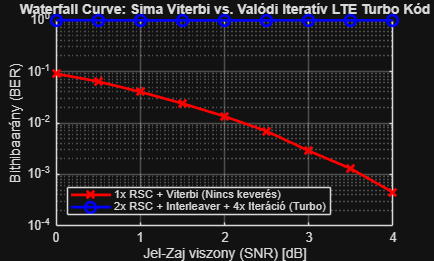


%% --- Eredmények kirajzolása ---
figure('Name', 'Valós Turbo Kód Teljesítménye', 'NumberTitle', 'off');
semilogy(snr_dB_array, ber_viterbi, 'r-x', 'LineWidth', 2, 'MarkerSize', 8); hold on;
semilogy(snr_dB_array, ber_turbo, 'b-o', 'LineWidth', 2, 'MarkerSize', 8);
grid on;
title('Waterfall Curve: Sima Viterbi vs. Valódi Iteratív LTE Turbo Kód');
xlabel('Jel-Zaj viszony (SNR) [dB]');
ylabel('Bithibaarány (BER)');
legend('1x RSC + Viterbi (Nincs keverés)', '2x RSC + Interleaver + 4x Iteráció (Turbo)', 'Location', 'southwest');